# Proyecto Final: MyShazam II

clear;
close all;

#### Cargue de datos:

Cargamos la canción a ser procesada:

[funsound, fs_funsound]=mp3read('funsound.mp3');

Graficamos la señal de funsound.mp3:

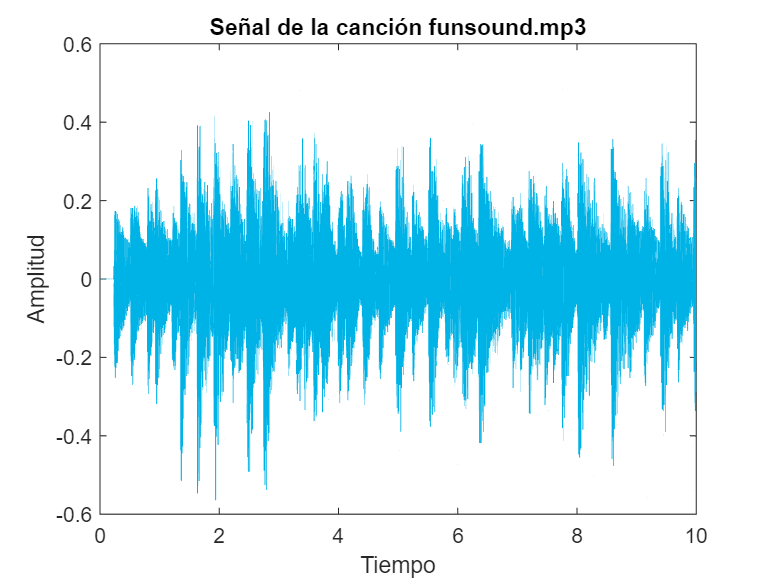

tiempo=size (funsound,1)/fs_funsound;
x=0:1/fs_funsound:tiempo;
plot(x(2:end),funsound,'Color',[0,0.7,0.9]),xlim([0 tiempo]);
title('Señal de la canción funsound.mp3')
xlabel('Tiempo')
ylabel('Amplitud')

Separamos los canales izquierdo y derecho para la canción:

canal1_funsound =funsound(:,1);
canal2_funsound =funsound(:,2);

Graficamos la señal dada por el canal 1:

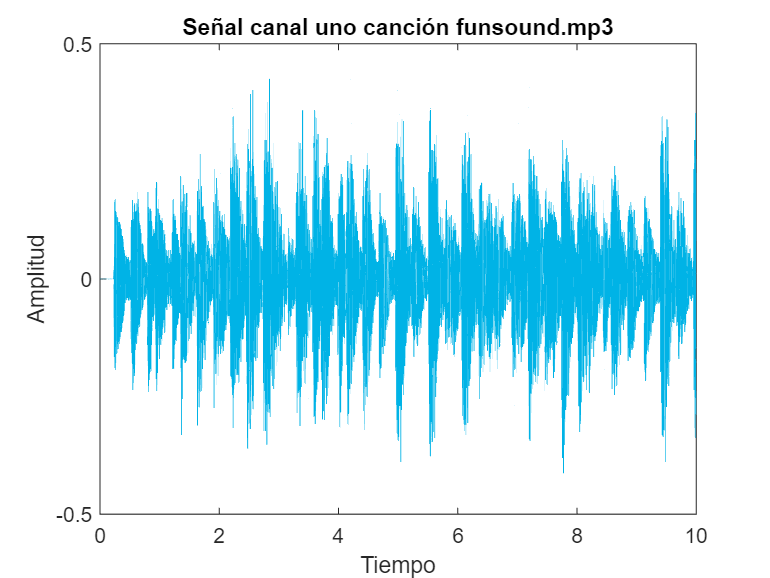

tiempo=size (canal1_funsound,1)/fs_funsound;
x=0:1/fs_funsound:tiempo;
plot(x(2:end),canal1_funsound,'Color',[0,0.7,0.9]),xlim([0 tiempo]);
title('Señal canal uno canción funsound.mp3')
xlabel('Tiempo')
ylabel('Amplitud')

#### **Preprocesamiento:**

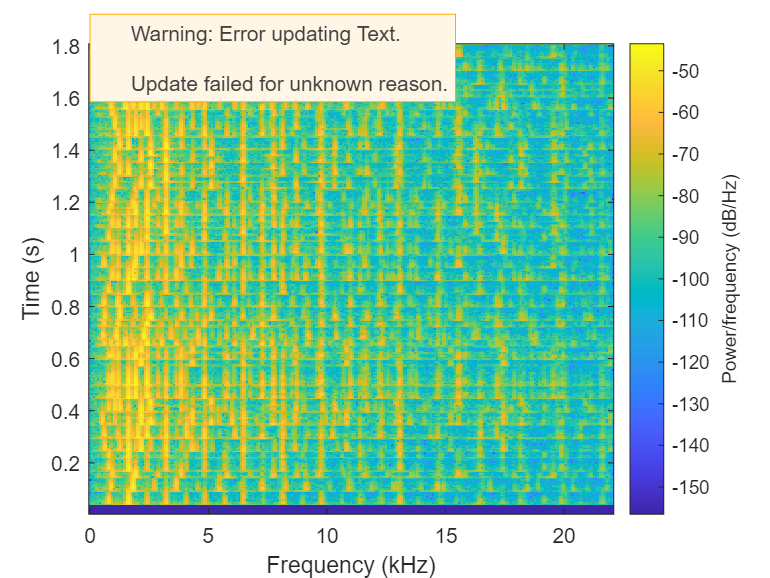

[y, fs_Muestra]=mp3read('funsound.mp3');
y=mean(y,2);
y_rs=resample(y,8000,fs_Muestra);
twindow=64e-3;
NWindow=twindow*8000;
window=hamming(NWindow);
nfft=512;
NOverlap = NWindow/2; 

[S, F, T] = spectrogram(y_rs, window, NOverlap, nfft, fs_Muestra);
spectrogram(y_rs, window, NOverlap, nfft, fs_Muestra);

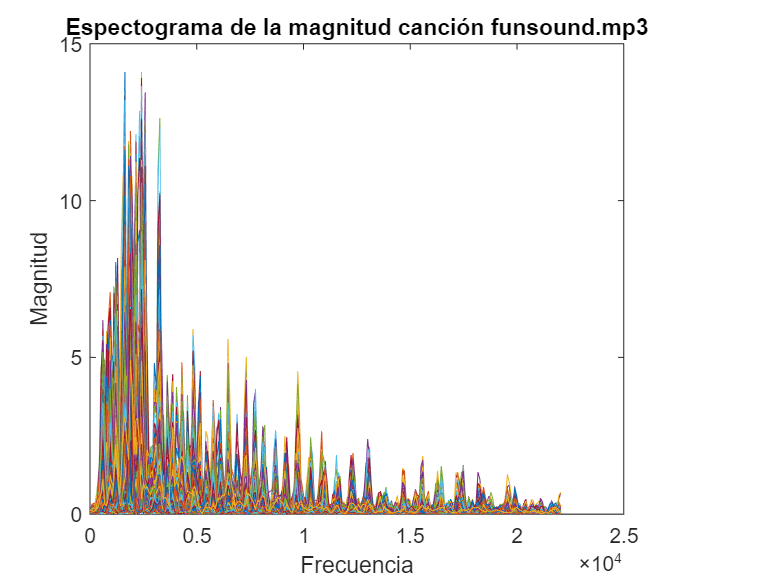

plot(F,abs(S));
title('Espectograma de la magnitud canción funsound.mp3')
xlabel('Frecuencia')
ylabel('Magnitud')

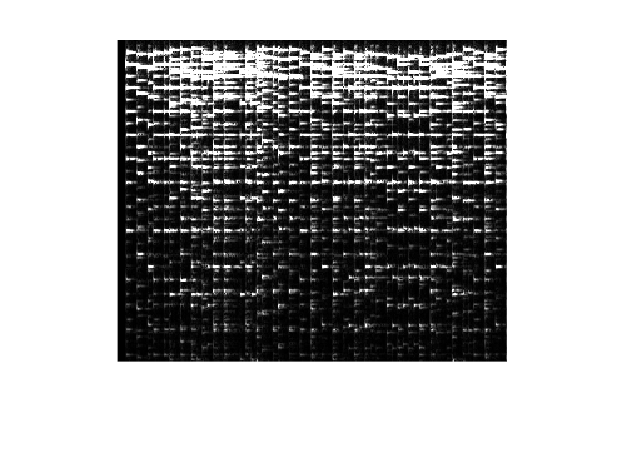

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.




imshow(abs(S));

#### Procesamiento:

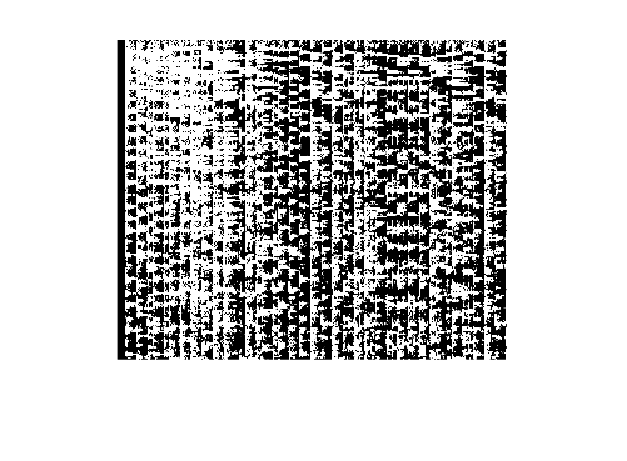

S = S(1:end-1,:);
F = F(1:end-1,:);
S = max(S, max(S(:))/1e6);
S = 10*log10(abs(S));

S = S - mean(S(:));
B = [1 -1]; A = [1 -0.98];
S = filter(B, A, S');
S = S';

imshow(S);


se = strel('rectangle', [20,20]); 
SDilated = imdilate(S,se);


[I, J] = find(SDilated == S);
maxes = [F(I), T(J)'];



Procedemos a la comparación de los máximos o picos:

L = zeros(length(maxes)*3,4);
pairs = 0; 


for i = 1:length(maxes)-1
    f1 = I(i);
    t1 = J(i);
    
    [R, C] = find((abs(I - f1) < 32) & ((J - t1) > 0) & ((J - t1) < 64), 3);
        
    
    for j = 1:length(R)
         Lrow = [t1, f1, I(R(j)) - f1, J(R(j)) - t1];
         pairs = pairs+1;
         L(pairs,:) = Lrow;       
    end 
end


L = L(1:pairs,:);

Convertimos a hash:

H = zeros([length(L), 3]);

for i = 1:length(H)
    
     
    initialFreq = L(i,2);
    Fdiff = L(i,3);
    initialTime = L(i,1);
    tDiff = L(i,4);
    
    %Creación del hash
    hash = (initialFreq-1)*2^12 + Fdiff*2^6 + tDiff;
    
end

**Comparación de una canción diferente: **

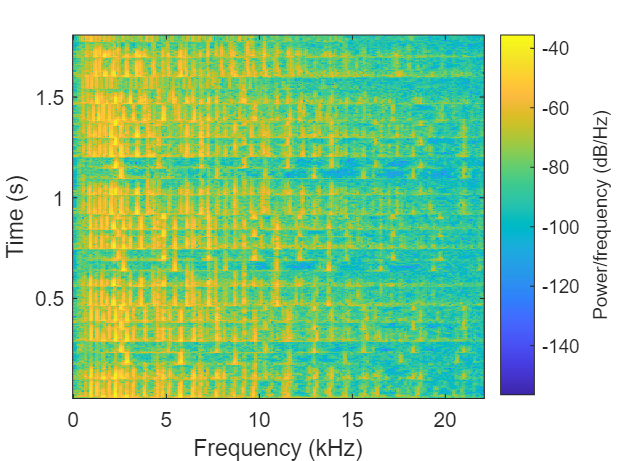

[y, fs_Muestra]=mp3read('pianotime.mp3');

y=mean(y,2);

y_rs=resample(y,8000,fs_Muestra);
twindow=64e-3;
NWindow=twindow*8000;
window=hamming(NWindow);
nfft=512;
NOverlap = NWindow/2; 

[S, F, T] = spectrogram(y_rs, window, NOverlap, nfft, fs_Muestra);
spectrogram(y_rs, window, NOverlap, nfft, fs_Muestra);

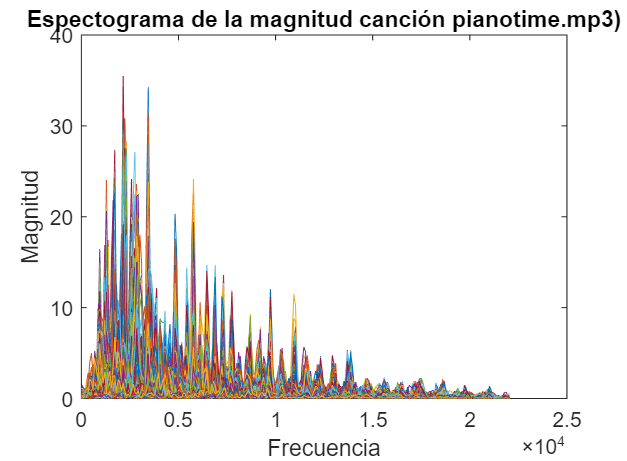


plot(F,abs(S));
title('Espectograma de la magnitud canción pianotime.mp3)')
xlabel('Frecuencia')
ylabel('Magnitud')

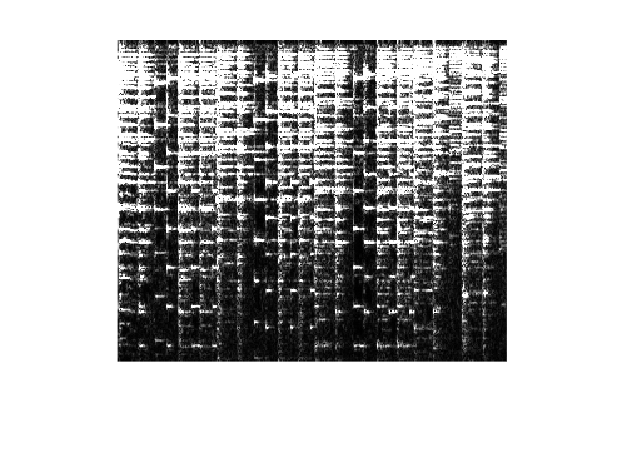


imshow(abs(S));

Realizamos el mismo proceso anterior para obtener el hash de la canción:

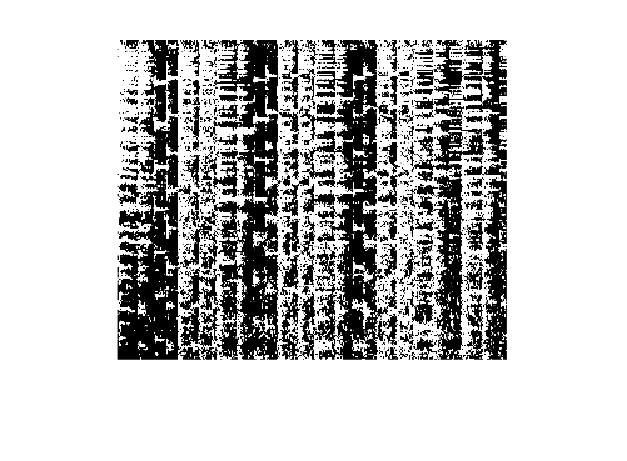

S = S(1:end-1,:);
F = F(1:end-1,:);
S = max(S, max(S(:))/1e6);
S = 10*log10(abs(S));

S = S - mean(S(:));
B = [1 -1]; A = [1 -0.98];
S = filter(B, A, S');
S = S';

imshow(S);


se = strel('rectangle', [20,20]); 
SDilated = imdilate(S,se);


[I, J] = find(SDilated == S);
maxes = [F(I), T(J)'];



Emparejamos los máximos/picos:

L = zeros(length(maxes)*3,4);
pairs = 0; 


for i = 1:length(maxes)-1
    f1 = I(i);
    t1 = J(i);
    
    [R, C] = find((abs(I - f1) < 32) & ((J - t1) > 0) & ((J - t1) < 64), 3);
        
    for j = 1:length(R)
         Lrow = [t1, f1, I(R(j)) - f1, J(R(j)) - t1];
         pairs = pairs+1;
         L(pairs,:) = Lrow;       
    end 
end


L = L(1:pairs,:);

Convertimos a hash:

H = zeros([length(L), 3]);

for i = 1:length(H)
    
    initialFreq = L(i,2);
    Fdiff = L(i,3);
    initialTime = L(i,1);
    tDiff = L(i,4);
    hash2 = (initialFreq-1)*2^12 + Fdiff*2^6 + tDiff;
    
end

Comparamos para saber si son la misma canción:

if  hash==hash2
    disp('Son la misma canción');
else
    disp('No son la misma canción');
end

No son la misma canción


**Comparación de la misma canción:**

Cargamos la canción que queremos comparar:

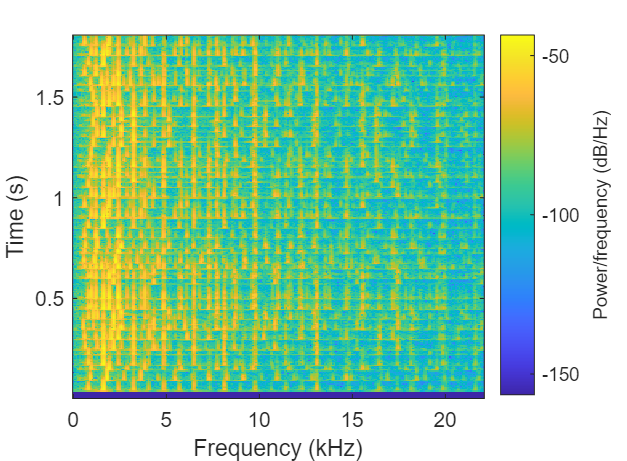

[y, fs_Muestra]=mp3read('funsound.mp3');

y=mean(y,2);

y_rs=resample(y,8000,fs_Muestra);
twindow=64e-3;
NWindow=twindow*8000;
window=hamming(NWindow);
nfft=512;
NOverlap = NWindow/2; 

[S, F, T] = spectrogram(y_rs, window, NOverlap, nfft, fs_Muestra);
spectrogram(y_rs, window, NOverlap, nfft, fs_Muestra);

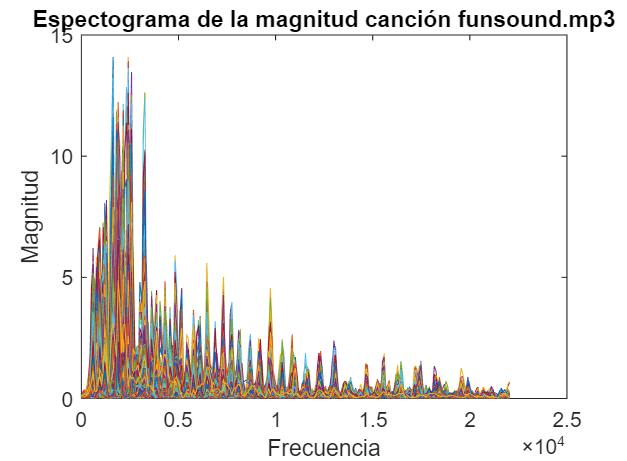


plot(F,abs(S));
title('Espectograma de la magnitud canción funsound.mp3')
xlabel('Frecuencia')
ylabel('Magnitud')


imshow(abs(S));

Realizamos el mismo proceso anterior para obtener el hash de la canción:

S = S(1:end-1,:);
F = F(1:end-1,:);
S = max(S, max(S(:))/1e6);
S = 10*log10(abs(S));

S = S - mean(S(:));
B = [1 -1]; A = [1 -0.98];
S = filter(B, A, S');
S = S';

imshow(S);


se = strel('rectangle', [20,20]); 
SDilated = imdilate(S,se);


[I, J] = find(SDilated == S);
maxes = [F(I), T(J)'];



Emparejamos los máximos/picos:

L = zeros(length(maxes)*3,4);
pairs = 0; 


for i = 1:length(maxes)-1
    f1 = I(i);
    t1 = J(i);
    
    [R, C] = find((abs(I - f1) < 32) & ((J - t1) > 0) & ((J - t1) < 64), 3);
        
    for j = 1:length(R)
         Lrow = [t1, f1, I(R(j)) - f1, J(R(j)) - t1];
         pairs = pairs+1;
         L(pairs,:) = Lrow;       
    end 
end


L = L(1:pairs,:);

Convertimos a hash:

H = zeros([length(L), 3]);

for i = 1:length(H)
    
    initialFreq = L(i,2);
    Fdiff = L(i,3);
    initialTime = L(i,1);
    tDiff = L(i,4);
    hash2 = (initialFreq-1)*2^12 + Fdiff*2^6 + tDiff;
    
end

Comparamos para saber si son la misma canción:

if  hash==hash2
    disp('Son la misma canción');
else
    disp('No son la misma canción');
end

Son la misma canción
